clear
clc
syms x
f_2 = taylor(cos(x),x,'ExpansionPoint',0.785,'Order', 2)

$$f\_2 = \cos\left(\frac{157}{200}\right)-\sin\left(\frac{157}{200}\right)\,\left(x-\frac{157}{200}\right)$$

f_3 = taylor(cos(x),x,'ExpansionPoint',0.785,'Order', 3)

$$f\_3 = \cos\left(\frac{157}{200}\right)-\sin\left(\frac{157}{200}\right)\,\left(x-\frac{157}{200}\right)-\frac{\cos\left(\frac{157}{200}\right)\,{\left(x-\frac{157}{200}\right)}^{2}}{2}$$

f_4 = taylor(cos(x),x,'ExpansionPoint',0.785,'Order', 4)

$$f\_4 = \cos\left(\frac{157}{200}\right)+\frac{\sin\left(\frac{157}{200}\right)\,{\left(x-\frac{157}{200}\right)}^{3}}{6}-\sin\left(\frac{157}{200}\right)\,\left(x-\frac{157}{200}\right)-\frac{\cos\left(\frac{157}{200}\right)\,{\left(x-\frac{157}{200}\right)}^{2}}{2}$$

f_5 = taylor(cos(x),x,'ExpansionPoint',0.785,'Order', 5)

$$f\_5 = \cos\left(\frac{157}{200}\right)+\frac{\sin\left(\frac{157}{200}\right)\,{\left(x-\frac{157}{200}\right)}^{3}}{6}-\sin\left(\frac{157}{200}\right)\,\left(x-\frac{157}{200}\right)-\frac{\cos\left(\frac{157}{200}\right)\,{\left(x-\frac{157}{200}\right)}^{2}}{2}+\frac{\cos\left(\frac{157}{200}\right)\,{\left(x-\frac{157}{200}\right)}^{4}}{24}$$

x = 0:0.01:0.5*pi

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


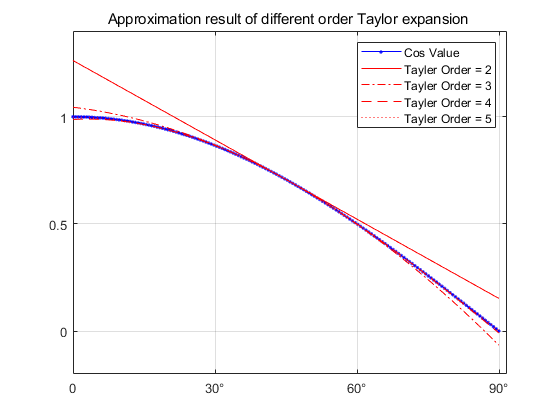

f_2 = eval(f_2);
f_3 = eval(f_3);
f_4 = eval(f_4);
f_5 = eval(f_5);
plot(x,cos(x),"Marker",".",'Color','b')
hold on 
plot(x,f_2,'Color','r','LineStyle','-')
hold on
plot(x,f_3,'Color','r','LineStyle','-.')
hold on
plot(x,f_4,'Color','r','LineStyle','--')
hold on
plot(x,f_5,'Color','r','LineStyle',':')
grid on
xticks([0 pi/6 pi/3 pi/2])
xticklabels({'0','30°','60°','90°'})
yticks([0 0.5 1])
legend('Cos Value','Tayler Order = 2'...
  ,'Tayler Order = 3','Tayler Order = 4','Tayler Order = 5')
title('Approximation result of different order Taylor expansion ')

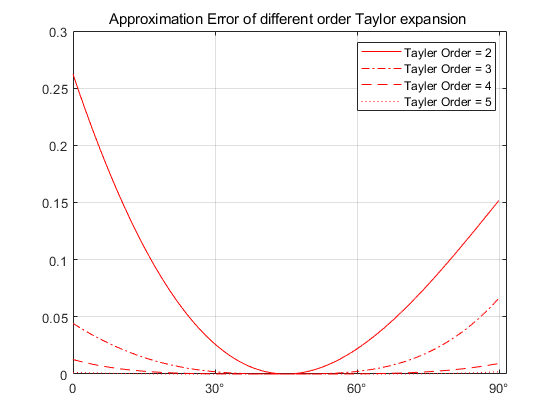

err_2 = abs(cos(x) - f_2);
err_3 = abs(cos(x) - f_3);
err_4 = abs(cos(x) - f_4);
err_5 = abs(cos(x) - f_5);
figure

plot(x,err_2,'Color','r','LineStyle','-')
hold on
plot(x,err_3,'Color','r','LineStyle','-.')
hold on
plot(x,err_4,'Color','r','LineStyle','--')
hold on
plot(x,err_5,'Color','r','LineStyle',':')
grid on
xticks([0 pi/6 pi/3 pi/2])
xticklabels({'0','30°','60°','90°'})
%yticks([0 0.5 1])
legend('Tayler Order = 2'...
  ,'Tayler Order = 3','Tayler Order = 4','Tayler Order = 5')
title('Approximation Error of different order Taylor expansion ')